## Finding the Port of the Instrument

- Power on the instrument

- Connect the instrument to your computer

- Identify the port that the instrument/s are connected to

clear
% After powering on and connecting the instrument
% Scan ports on computer
port_list = serialportlist;

% Printing out ports
for i = 1:numel(port_list)
    fprintf ("Port #%d: %s\n", i, port_list(i))
end

Port #1: /dev/cu.EthansQC45
Port #2: /dev/tty.EthansQC45
Port #3: /dev/cu.Bluetooth-Incoming-Port
Port #4: /dev/tty.Bluetooth-Incoming-Port
Port #5: /dev/cu.usbserial-A9083ZTE
Port #6: /dev/tty.usbserial-A9083ZTE


## Connecting to the Instrument

- Choose the correct port

- Set dev1 variable to the correct port

- Create object and connect to the device

% On Mac you might get something similar to this:
% "/dev/tty.usbserial-AR0KM0M8"

% On Windows you might get soothing similar to this:
% "COM3"
% From device manager you can also find the port number
% Look for "USB Serial Port (COM3)"
% The number will vary between computers

% Set your device variables equal to the ports
dev1 = 6; % Port number of device 1


% Creating an object for the serial communications
device1 = serialport(port_list(dev1), 38400)

device1 =   Serialport with properties:

                 Port: "/dev/tty.usbserial-A9083ZTE"
             BaudRate: 38400
    NumBytesAvailable: 0

  Show all properties, functions


## Sending the First Commands

- Write a command to the instrument

- Read the information from the instrument

- Get device information from instruments with basic commands

writeline(device1, "*idn?");
dev1idn = readline(device1);
fprintf("Device 1: %s", dev1idn)

Device 1: Arroyo 6310 190815543 v2.19 251


## Changing Current and Enabling Output

- Changing Current and Enabling Output

- Change the Iset of the device

- Enable the output of the device

- Exploring concatenation

% Changing the Iset
Iset = 500; % mAmps

% Creating the command and sending it to the device
Tcommand = sprintf("las:ldi %d", Iset);
writeline(device1, Tcommand);

% Enable the output
writeline(device1, "las:out 1");

% A note on concatenation
% Both commands can be combined by using the following syntax
% writeline(device1, "tec:t 25;out 0")

## Logging and Plotting Data

- Log and graph data over a user-defined amount of time

- User-defined log interval (1 Hz by default)

- Log all dynamic values

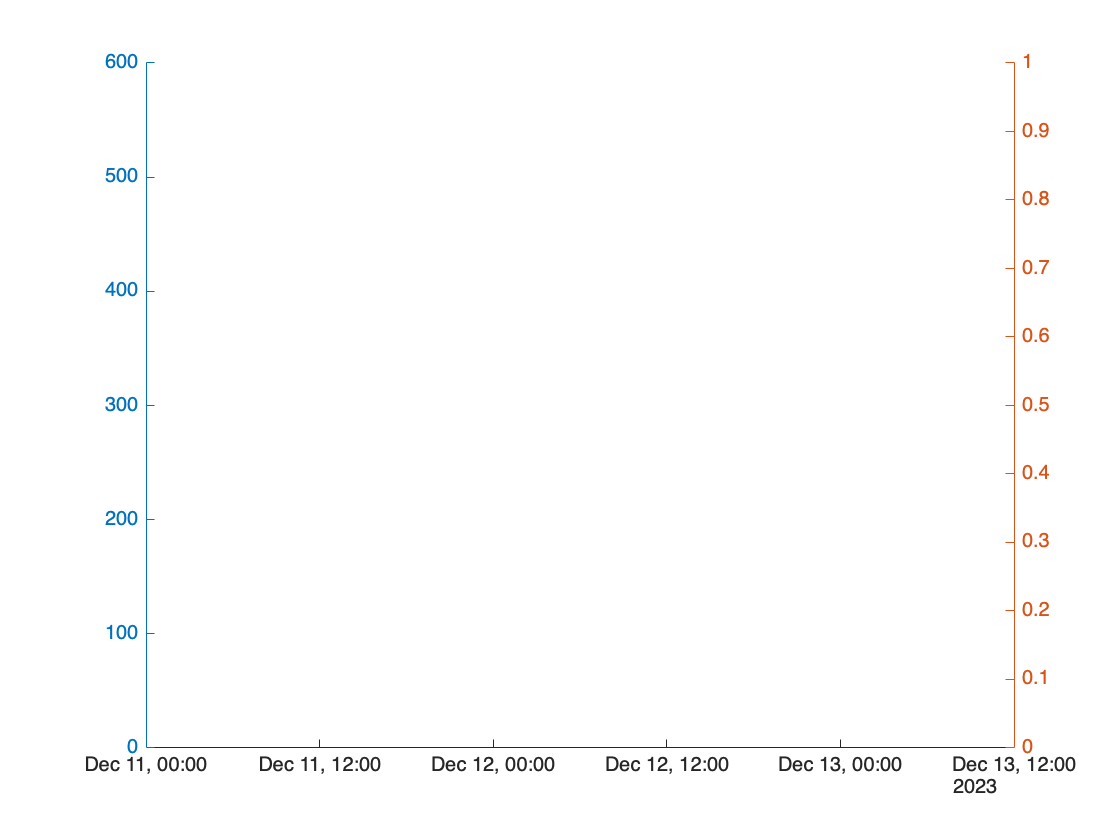

% Here are the user configured variables, adjust them to fit your purposes
% Configure polling frequency in hertz
polling_frequency = 1; %Hz

% Configure acquisition length in seconds
acquisition_length = 5; %sec

% Data lables for cell array
recorded_values = {"time",  "current",  "voltage",  "diode current",  "diode power"};

figure(1)
ivd_plot = axes();
hold(ivd_plot, "on");



% Begin reading data
for readings = 1:(polling_frequency*acquisition_length)
    % Querey and recieve time, current, voltage, diode current, and diode power
    writeline(device1, "time?;las:i?;ldv?;mdi?;mdp?");
    raw_data = readline(device1);

    % Parse raw data
    parsed_data = strings(0);
    [token,~] = split(raw_data, ',');
    parsed_data = [parsed_data ; token];

    % fix time formatting
    time_variables = split(parsed_data(1), ':');
    t = sprintf("%s:%s:%s", time_variables(2:4));
    formatted_time = datetime(t, InputFormat = "HH:mm:ss.SS");
    
    % Create cell array with captured data
    recorded_values(end+1, :) = ...
    {
        formatted_time, 
        str2double(parsed_data(2)),
        str2double(parsed_data(3)),
        str2double(parsed_data(4)),
        str2double(parsed_data(5))
    };

    %Plot current, voltage, diode current versus time
    yyaxis left;
    plot( ...
        [recorded_values{2:end,1}],[recorded_values{2:end,2}], ... % Current
        [recorded_values{2:end,1}],[recorded_values{2:end,3}], ... % Voltage 
        "Parent", ivd_plot);
    plot( ...
        [recorded_values{2:end,1}],[recorded_values{2:end,4}], ... % Diode Current
        "Parent", ivd_plot);
    drawnow;
    pause(1/polling_frequency);

end


% Plot formatting
grid(ivd_plot,"on");
title(ivd_plot, "current, voltage, diode current versus time");
xlabel(ivd_plot, "Time");
xtickangle(ivd_plot, 45);
xtickformat(ivd_plot,"auto")
legend(ivd_plot, "Current(A)", "Voltage (V)", "Diode Current(A)");

## Ramping current and logging data

- Ramping current and logging data to create a LVI plot

- User selected current range and step size

- Change set point and turn output on

- Log all dynamic values

% Configure Min and Max Current
min_i = 0; %mAmps
max_i = 500; %mAmps

% Configure step size
step_size = 20; %mAmps

% Configure dwell time
dwell_time = 0.1; %seconds


% Begin ramping
% Changing the Iset
Iset = min_i;

% Data lables for cell array
LVI_values = {"time",  "current",  "voltage",  "diode current",  "diode power", "Iset"};

figure(2)
LVI_plot = axes();
hold(LVI_plot, "on");


% Creating las command and sending it to the device
las_command = sprintf("las:ldi %d;out 1", Iset);
writeline(device1, las_command)

acquiring = 1;

% Begin reading data
while acquiring
    % Query and receive time, current, voltage, diode current, and diode power
    pause(dwell_time)
    writeline(device1, "time?;las:i?;ldv?;mdi?;mdp?");
    raw_data = readline(device1);

    % Parse raw data
    parsed_data = strings(0);
    [token,~] = split(raw_data, ',');
    parsed_data = [parsed_data ; token];

    % fix time formatting
    time_variables = split(parsed_data(1), ':');
    t = sprintf("%s:%s:%s", time_variables(2:4));
    formatted_time = datetime(t, InputFormat = "HH:mm:ss.SS");
    
    % Create cell array with captured data
    LVI_values(end+1, :) = ...
    {
        formatted_time, 
        str2double(parsed_data(2)),
        str2double(parsed_data(3)),
        str2double(parsed_data(4)),
        str2double(parsed_data(5)),
        Iset
    };
    %Plot voltage, diode current, versus current
    yyaxis left;
    plot( ...
        [LVI_values{2:end,2}],[LVI_values{2:end,3}], ... % Voltage
        "Parent", LVI_plot);
    yyaxis right;
    plot( ...
        [LVI_values{2:end,2}],[LVI_values{2:end,4}], ... % Diode Current
        "Parent", LVI_plot);
    drawnow;
    
    if Iset <= max_i-step_size
        Iset = Iset + step_size;
        las_command = sprintf("las:ldi %d;out 1", Iset);
        writeline(device1, las_command);
        pause(.04); % Allow command to be sent
    else
        acquiring = 0;
    end
end

% Plot formatting
grid(LVI_plot,"on");
title(LVI_plot, "LVI Plot");
xlabel(LVI_plot, "Time");
xtickangle(LVI_plot, 45);
xtickformat(LVI_plot,"auto")
legend(LVI_plot, "Voltage (V)", "Diode Current(mA)");